# 
$$1^{st}\text{ tutorial in IVP}\\
31^{st} January\text{ 2024}\\
\text{Written by - Anurag Paul, 20EC01045.}$$


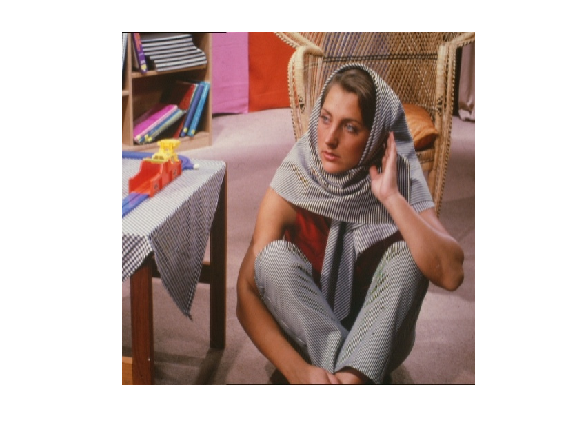

% input image
i = imread('https://i.stack.imgur.com/Ips0H.jpg');
imshow(i);

## 
$$\text{To grayscale the image.}$$


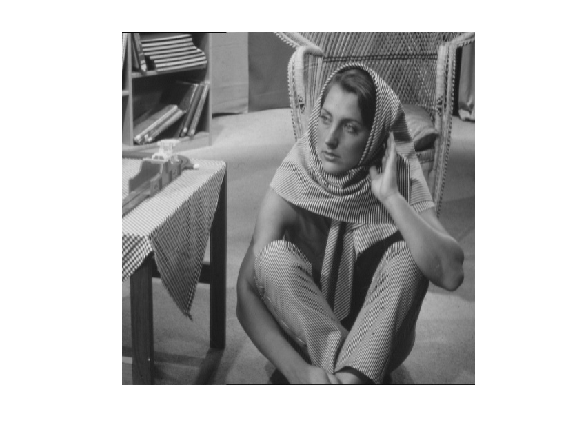

g = rgb2gray(i); imshow(g);

max(g, [], 'all')

ans = uint8
235

size(g)

ans =    512   512


## 
$$\text{Rotate the image by }45^\circ\text{ clockwise.}$$


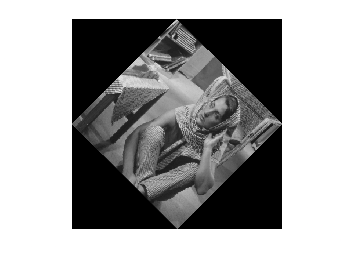

r = imrotate(g,-45); imshow(r);

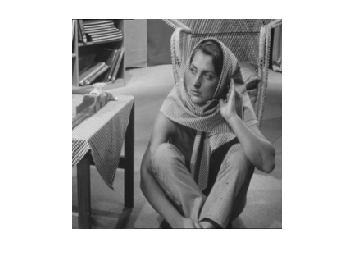

% Shrink Image By Factor of Two Using Default
% Interpolation Method
re = imresize( g , .5 ); imshow(re);

max(re, [], 'all')

ans = uint8
232

size(re)

ans =    256   256


## 
$$\text{Bit-plane slicing.}$$


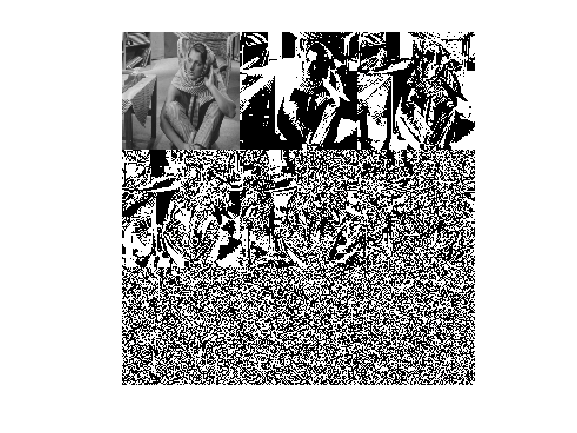

c = cell(1,9); c{1} = g;
for r = 7:-1:0
    c{9-r} = bitand(g, 2^r)&1;
end
montage(c); % MSB to LSB

## 
$$\text{Bit-wise AND of matrix elements with }2^r\text{ to}\\
\text{extract }r^{th}\text{ bit}.\\
&\text{ with 1 to convert image to binary}.$$
